% Netwon Method for Least Squares

clear
clc

syms y1 A omega phi t1
R = y1 + A*sin(omega*t1+phi)




% matlabFunction(f)

clear 
clc

a = [1 2 3];
syms x i 

i = [1 2 3]
f = x.^i
y = f*a'

% F = symsum(f,i,1,3) 

clear
clc

t = [1 2 3 4 5]';

y = [6 7 8 9 10]';

syms A omega phi
fn = A*sin(omega*t + phi)

$$fn = \left(\begin{array}{c} A\,\sin\left(\omega +\varphi \right)\\ A\,\sin\left(2\,\omega +\varphi \right)\\ A\,\sin\left(3\,\omega +\varphi \right)\\ A\,\sin\left(4\,\omega +\varphi \right)\\ A\,\sin\left(5\,\omega +\varphi \right) \end{array}\right)$$


I1 = y-fn

$$I1 = \left(\begin{array}{c} 6-A\,\sin\left(\omega +\varphi \right)\\ 7-A\,\sin\left(2\,\omega +\varphi \right)\\ 8-A\,\sin\left(3\,\omega +\varphi \right)\\ 9-A\,\sin\left(4\,\omega +\varphi \right)\\ 10-A\,\sin\left(5\,\omega +\varphi \right) \end{array}\right)$$


I2 = y'- A*sin(omega*t' + phi) 

$$I2 = \left(\begin{array}{ccccc} 6-A\,\sin\left(\omega +\varphi \right) & 7-A\,\sin\left(2\,\omega +\varphi \right) & 8-A\,\sin\left(3\,\omega +\varphi \right) & 9-A\,\sin\left(4\,\omega +\varphi \right) & 10-A\,\sin\left(5\,\omega +\varphi \right) \end{array}\right)$$

% FX = sum((y-fn).^2)

$$I3 = {\left(A\,\sin\left(\omega +\varphi \right)-6\right)}^{2}+{\left(A\,\sin\left(2\,\omega +\varphi \right)-7\right)}^{2}+{\left(A\,\sin\left(3\,\omega +\varphi \right)-8\right)}^{2}+{\left(A\,\sin\left(4\,\omega +\varphi \right)-9\right)}^{2}+{\left(A\,\sin\left(5\,\omega +\varphi \right)-10\right)}^{2}$$

FX = I2*I1 % Objective Function in Symbolic Form

$$FX = {\left(A\,\sin\left(\omega +\varphi \right)-6\right)}^{2}+{\left(A\,\sin\left(2\,\omega +\varphi \right)-7\right)}^{2}+{\left(A\,\sin\left(3\,\omega +\varphi \right)-8\right)}^{2}+{\left(A\,\sin\left(4\,\omega +\varphi \right)-9\right)}^{2}+{\left(A\,\sin\left(5\,\omega +\varphi \right)-10\right)}^{2}$$



g_Fx = gradient(FX)

$$g\_Fx = \begin{array}{l} \left(\begin{array}{c} 2\,\sigma_{4}\,\left(A\,\sigma_{4}-7\right)+2\,\sigma_{3}\,\left(A\,\sigma_{3}-8\right)+2\,\sigma_{2}\,\left(A\,\sigma_{2}-9\right)+2\,\sigma_{1}\,\left(A\,\sigma_{1}-10\right)+2\,\sin\left(\omega +\varphi \right)\,\sigma_{10}\\ 4\,A\,\sigma_{8}\,\left(A\,\sigma_{4}-7\right)+6\,A\,\sigma_{7}\,\left(A\,\sigma_{3}-8\right)+8\,A\,\sigma_{6}\,\left(A\,\sigma_{2}-9\right)+10\,A\,\sigma_{5}\,\left(A\,\sigma_{1}-10\right)+\sigma_{9}\\ 2\,A\,\sigma_{8}\,\left(A\,\sigma_{4}-7\right)+2\,A\,\sigma_{7}\,\left(A\,\sigma_{3}-8\right)+2\,A\,\sigma_{6}\,\left(A\,\sigma_{2}-9\right)+2\,A\,\sigma_{5}\,\left(A\,\sigma_{1}-10\right)+\sigma_{9} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(5\,\omega +\varphi \right)\\ \sigma_{2}=\sin\left(4\,\omega +\varphi \right)\\ \sigma_{3}=\sin\left(3\,\omega +\varphi \right)\\ \sigma_{4}=\sin\left(2\,\omega +\varphi \right)\\ \sigma_{5}=\cos\left(5\,\omega +\varphi \right)\\ \sigma_{6}=\cos\left(4\,\omega +\varphi \right)\\ \sigma_{7}=\cos\left(3\,\omega +\varphi \right)\\ \sigma_{8}=\cos\left(2\,\omega +\varphi \right)\\ \sigma_{9}=2\,A\,\cos\left(\omega +\varphi \right)\,\sigma_{10}\\ \sigma_{10}=A\,\sin\left(\omega +\varphi \right)-6 \end{array}$$


h_Fx = hessian(FX)


f = matlabFunction(FX);
g = matlabFunction(g_Fx);
h = matlabFunction(h_Fx);

X = [5 1 0]';


X = X - ( h(X(1),X(2),X(3))^(-1) * g(X(1),X(2),X(3)) )

X =    -2.9361
    0.7404
    1.1520



f(X(1),X(2),X(3))

ans = 295.4678

syms x
f= x^3 + x^2 + 2*x*(x+9 +3*x)
y= simplify(f)

z = matlabFunction(y)




clear
clc

% Data was generate in the following manner 
% 
% x = 0:0.25:pi*2;
% y = 5*sin(x); % ORIGINAL SIGNAL
% plot(x,y);
% hold on 
% 
% g_noise = randn(1,length(x));
% 
% signal = y + g_noise;
%
%


t = [0	0.250000000000000	0.500000000000000	0.750000000000000	1	1.25000000000000	1.50000000000000	1.75000000000000	2	2.25000000000000	2.50000000000000	2.75000000000000	3	3.25000000000000	3.50000000000000	3.75000000000000	4	4.25000000000000	4.50000000000000	4.75000000000000	5	5.25000000000000	5.50000000000000	5.75000000000000	6	6.25000000000000]';
t = round(t,2,"significant")

y = [0.802184648027535	0.768195431436988	2.35053531869442 3.76164683489910	2.95055436085519	3.70889165889840	4.56051224525674 4.99759841380172	6.33741739308901	4.68762911984651	2.54985997969508	1.27921386874684	2.23939631162545	2.19256470866270	-1.58647706096305	-3.33667175931440	-5.19666635972145	-3.49995873607394	-4.59793160410695	-3.83105569378474	-5.70332698963458	-4.05409742990351	-4.18174796304358	-1.26644084918958	-1.94826810193057	-0.253304951019571]';
y = round(y,2,"significant")

syms A omega phi
fn = A*sin(omega*t + phi)

I1 = y-fn

I2 = y'- A*sin(omega*t' + phi) 

FX = I2*I1 % Objective Function in Symbolic Form


g_Fx = gradient(FX)

h_Fx = hessian(FX)

f = matlabFunction(FX);
g = matlabFunction(g_Fx);
h = matlabFunction(h_Fx);

X = [5 1 0]';
f(5, 1, 0) % smallest value of error possible (see how data was generated)

X = X - ( h(X(1),X(2),X(3))^(-1) * g(X(1),X(2),X(3)) )

f(X(1),X(2),X(3))


clear
clc 

data_points = [0.802184648027535	0.768195431436988	2.35053531869442 3.76164683489910	2.95055436085519	3.70889165889840	4.56051224525674 4.99759841380172	6.33741739308901	4.68762911984651	2.54985997969508	1.27921386874684	2.23939631162545	2.19256470866270	-1.58647706096305	-3.33667175931440	-5.19666635972145	-3.49995873607394	-4.59793160410695	-3.83105569378474	-5.70332698963458	-4.05409742990351	-4.18174796304358	-1.26644084918958	-1.94826810193057	-0.253304951019571];

time_stamps = [0	0.250000000000000	0.500000000000000	0.750000000000000	1	1.25000000000000	1.50000000000000	1.75000000000000	2	2.25000000000000	2.50000000000000	2.75000000000000	3	3.25000000000000	3.50000000000000	3.75000000000000	4	4.25000000000000	4.50000000000000	4.75000000000000	5	5.25000000000000	5.50000000000000	5.75000000000000	6	6.25000000000000];

stem(time_stamps,data_points)




clear
clc
close all
% Data was generate in the following manner 
% 
% x = 0:0.25:pi*2;
% y = 5*sin(x); % ORIGINAL SIGNAL
% plot(x,y);
% hold on 
% 
% g_noise = randn(1,length(x));
% 
% signal = y + g_noise;
%
%


t = [0	0.250000000000000	0.500000000000000	0.750000000000000	1	1.25000000000000	1.50000000000000	1.75000000000000	2	2.25000000000000	2.50000000000000	2.75000000000000	3	3.25000000000000	3.50000000000000	3.75000000000000	4	4.25000000000000	4.50000000000000	4.75000000000000	5	5.25000000000000	5.50000000000000	5.75000000000000	6	6.25000000000000]';
t = round(t,2,"significant")

y = [0.802184648027535	0.768195431436988	2.35053531869442 3.76164683489910	2.95055436085519	3.70889165889840	4.56051224525674 4.99759841380172	6.33741739308901	4.68762911984651	2.54985997969508	1.27921386874684	2.23939631162545	2.19256470866270	-1.58647706096305	-3.33667175931440	-5.19666635972145	-3.49995873607394	-4.59793160410695	-3.83105569378474	-5.70332698963458	-4.05409742990351	-4.18174796304358	-1.26644084918958	-1.94826810193057	-0.253304951019571]';
y = round(y,2,"significant")

syms A omega phi
fn = A*sin(omega*t + phi)

I1 = y-fn

I2 = y'- A*sin(omega*t' + phi) 

FX = I2*I1 % Objective Function in Symbolic Form


g_Fx = gradient(FX)

h_Fx = hessian(FX)

f = matlabFunction(FX);
g = matlabFunction(g_Fx);
h = matlabFunction(h_Fx);

X = [5 1 0]';
f(5, 1, 0) % smallest value of error possible (see how data was generated)

X = [1 1 1]';
% Itteration 1
X = X - ( h(X(1),X(2),X(3))^(-1) * g(X(1),X(2),X(3)) )

f(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))

% Itteration 2
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))
% Itteration 3
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))
% Itteration 4
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))

% Itteration 5
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))
% Itteration 6
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))
% Itteration 7
X = X - h(X(1),X(2),X(3))^-1 * g(X(1),X(2),X(3))

FunctionValue = f(X(1),X(2),X(3))



% Beacause the point X = [1 1 1] is far from the min, its not converging
% Using modified Netwon Method would be good idea

% The value for function is increasing as algo goes on , hence descent
% condition is not met
% Check if Hessian is positive definite

H = h(X(1),X(2),X(3))
% ChatGPT says Cholesky decomposition only works on positive definite
% matrix

chol(H) % If throws an error than H is not positive definite matrix

% Use Levenberg-Marquardt's Modification




% Levenberg-Marquardt's Modification

clear
clc
close all
% Data was generate in the following manner 
% 
% x = 0:0.25:pi*2;
% y = 5*sin(x); % ORIGINAL SIGNAL
% plot(x,y);
% hold on 
% 
% g_noise = randn(1,length(x));
% 
% signal = y + g_noise;
%
%


t = [0	0.250000000000000	0.500000000000000	0.750000000000000	1	1.25000000000000	1.50000000000000	1.75000000000000	2	2.25000000000000	2.50000000000000	2.75000000000000	3	3.25000000000000	3.50000000000000	3.75000000000000	4	4.25000000000000	4.50000000000000	4.75000000000000	5	5.25000000000000	5.50000000000000	5.75000000000000	6	6.25000000000000]';
t = round(t,2,"significant");

y = [0.802184648027535	0.768195431436988	2.35053531869442 3.76164683489910	2.95055436085519	3.70889165889840	4.56051224525674 4.99759841380172	6.33741739308901	4.68762911984651	2.54985997969508	1.27921386874684	2.23939631162545	2.19256470866270	-1.58647706096305	-3.33667175931440	-5.19666635972145	-3.49995873607394	-4.59793160410695	-3.83105569378474	-5.70332698963458	-4.05409742990351	-4.18174796304358	-1.26644084918958	-1.94826810193057	-0.253304951019571]';
y = round(y,2,"significant");

syms A omega phi
fn = A*sin(omega*t + phi);

I1 = y-fn;

I2 = y'- A*sin(omega*t' + phi) ;

FX = I2*I1; % Objective Function in Symbolic Form


g_Fx = gradient(FX);

h_Fx = hessian(FX);

f = matlabFunction(FX);
g = matlabFunction(g_Fx);
h = matlabFunction(h_Fx);

X = [5 1 0]';
f(5, 1, 0); % smallest value of error possible (see how data was generated)

X = [1 1 1]'; 

uk = 600;
I = eye(3);

f_prev = 0;
f_current = 0;
epsilon = 1e-2;
delta = 1;

count = 1 

while delta > epsilon
    
    f_prev = f_current;
    X = X - ( (h(X(1),X(2),X(3)) + uk.*I)^(-1) * g(X(1),X(2),X(3)) )
    chol((h(X(1),X(2),X(3)) + uk.*I)^(-1));
    f_current = f(X(1),X(2),X(3))
    delta = abs(f_prev - f_current)
    count = count+1
    figure;
    stem(t,y)
    hold on
    plot(t,X(1)*sin(X(2)*t + X(3)))
    hold off

end


% Levenberg-Marquardt's Modification + Inital Guess based on stastastics of
% data

clear
clc
close all
% Data was generate in the following manner 
% 
% x = 0:0.25:pi*2;
% y = 5*sin(x); % ORIGINAL SIGNAL
% plot(x,y);
% hold on 
% 
% g_noise = randn(1,length(x));
% 
% signal = y + g_noise;
%
%


t = [0	0.250000000000000	0.500000000000000	0.750000000000000	1	1.25000000000000	1.50000000000000	1.75000000000000	2	2.25000000000000	2.50000000000000	2.75000000000000	3	3.25000000000000	3.50000000000000	3.75000000000000	4	4.25000000000000	4.50000000000000	4.75000000000000	5	5.25000000000000	5.50000000000000	5.75000000000000	6	6.25000000000000]';
t = round(t,2,"significant");

y = [0.802184648027535	0.768195431436988	2.35053531869442 3.76164683489910	2.95055436085519	3.70889165889840	4.56051224525674 4.99759841380172	6.33741739308901	4.68762911984651	2.54985997969508	1.27921386874684	2.23939631162545	2.19256470866270	-1.58647706096305	-3.33667175931440	-5.19666635972145	-3.49995873607394	-4.59793160410695	-3.83105569378474	-5.70332698963458	-4.05409742990351	-4.18174796304358	-1.26644084918958	-1.94826810193057	-0.253304951019571]';
y = round(y,2,"significant");

syms A omega phi
fn = A*sin(omega*t + phi);

I1 = y-fn;

I2 = y'- A*sin(omega*t' + phi) ;

FX = I2*I1; % Objective Function in Symbolic Form


g_Fx = gradient(FX);

h_Fx = hessian(FX);

f = matlabFunction(FX);
g = matlabFunction(g_Fx);
h = matlabFunction(h_Fx);

X = [5 1 0]';
f(5, 1, 0); % smallest value of error possible (see how data was generated)

Ai = rand(1)*(max(y) - mean(abs(y))) + mean(abs(y)); % inital guess for amplitude
% uniformly selected between max(amp) and mod mean(amp)
omegai = 1 ; % eye ball from the graph
phii = rand(1)*2*pi;

X = [Ai omegai phii]';
uk = 600;
I = eye(3);


f_prev = 0;
f_current = 0;
epsilon = 1e-2;
delta = 1;

count = 1 

count = 1

X =     3.6442
    1.0845
    5.8519


f_current = 59.3597

delta = 59.3597

count = 2

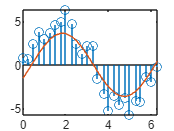

X =     3.6961
    1.0552
    5.9319


f_current = 52.5713

delta = 6.7884

count = 3

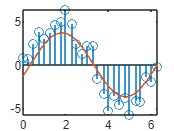

X =     3.7463
    1.0388
    5.9991


f_current = 47.8664

delta = 4.7049

count = 4

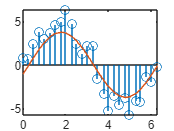

X =     3.7946
    1.0261
    6.0539


f_current = 44.3379

delta = 3.5286

count = 5

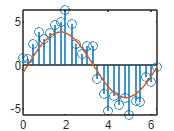

X =     3.8410
    1.0160
    6.0981


f_current = 41.6448

delta = 2.6931

count = 6

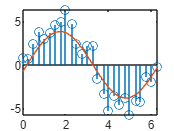

X =     3.8853
    1.0078
    6.1337


f_current = 39.5465

delta = 2.0983

count = 7

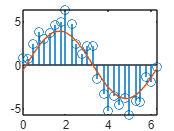

X =     3.9276
    1.0014
    6.1622


f_current = 37.8737

delta = 1.6728

count = 8

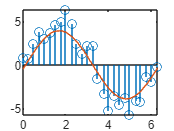

X =     3.9680
    0.9963
    6.1849


f_current = 36.5085

delta = 1.3652

count = 9

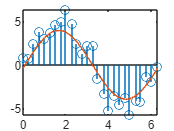

X =     4.0065
    0.9923
    6.2027


f_current = 35.3687

delta = 1.1398

count = 10

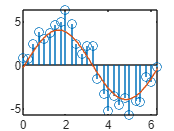

X =     4.0433
    0.9893
    6.2167


f_current = 34.3972

delta = 0.9715

count = 11

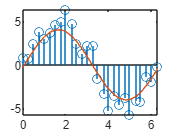

X =     4.0785
    0.9869
    6.2275


f_current = 33.5541

delta = 0.8432

count = 12

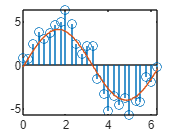

X =     4.1121
    0.9852
    6.2358


f_current = 32.8112

delta = 0.7429

count = 13

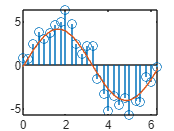

X =     4.1443
    0.9840
    6.2420


f_current = 32.1485

delta = 0.6626

count = 14

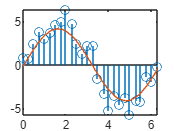

X =     4.1751
    0.9832
    6.2465


f_current = 31.5519

delta = 0.5967

count = 15

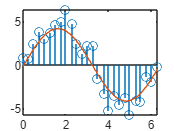

X =     4.2046
    0.9826
    6.2497


f_current = 31.0107

delta = 0.5412

count = 16

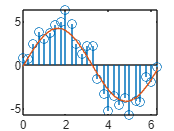

X =     4.2328
    0.9823
    6.2518


f_current = 30.5170

delta = 0.4936

count = 17

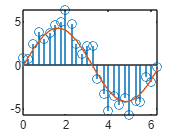

X =     4.2600
    0.9822
    6.2531


f_current = 30.0650

delta = 0.4520

count = 18

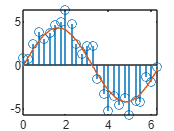

X =     4.2860
    0.9823
    6.2537


f_current = 29.6498

delta = 0.4152

count = 19

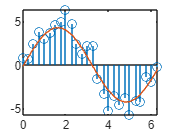

X =     4.3110
    0.9824
    6.2538


f_current = 29.2677

delta = 0.3821

count = 20

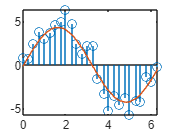

X =     4.3349
    0.9827
    6.2536


f_current = 28.9154

delta = 0.3523

count = 21

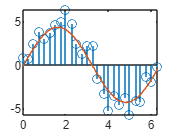

X =     4.3580
    0.9830
    6.2530


f_current = 28.5903

delta = 0.3251

count = 22

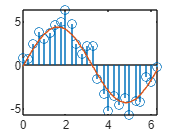

X =     4.3801
    0.9833
    6.2522


f_current = 28.2901

delta = 0.3002

count = 23

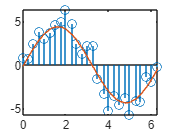

X =     4.4014
    0.9837
    6.2512


f_current = 28.0127

delta = 0.2774

count = 24

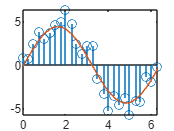

X =     4.4218
    0.9841
    6.2501


f_current = 27.7562

delta = 0.2564

count = 25

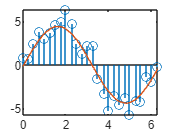

X =     4.4415
    0.9845
    6.2489


f_current = 27.5191

delta = 0.2371

count = 26

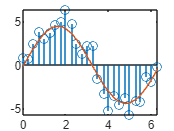

X =     4.4603
    0.9850
    6.2477


f_current = 27.2999

delta = 0.2193

count = 27

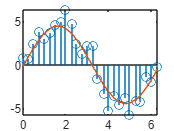

X =     4.4785
    0.9854
    6.2464


f_current = 27.0971

delta = 0.2028

count = 28

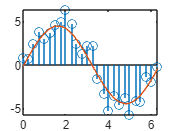

X =     4.4960
    0.9858
    6.2451


f_current = 26.9095

delta = 0.1876

count = 29

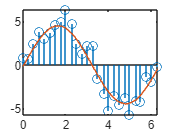

X =     4.5127
    0.9862
    6.2439


f_current = 26.7359

delta = 0.1735

count = 30

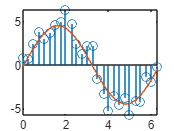

X =     4.5289
    0.9866
    6.2426


f_current = 26.5754

delta = 0.1605

count = 31

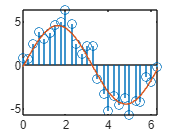

X =     4.5444
    0.9870
    6.2414


f_current = 26.4268

delta = 0.1485

count = 32

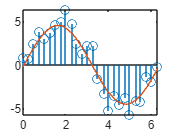

X =     4.5593
    0.9874
    6.2402


f_current = 26.2894

delta = 0.1374

count = 33

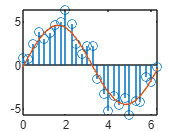

X =     4.5737
    0.9878
    6.2391


f_current = 26.1623

delta = 0.1271

count = 34

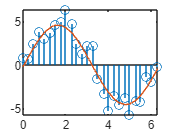

X =     4.5875
    0.9881
    6.2379


f_current = 26.0447

delta = 0.1176

count = 35

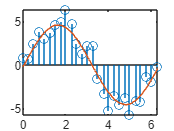

X =     4.6008
    0.9885
    6.2369


f_current = 25.9358

delta = 0.1088

count = 36

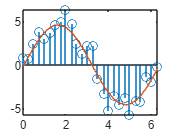

X =     4.6136
    0.9888
    6.2358


f_current = 25.8351

delta = 0.1007

count = 37

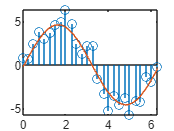

X =     4.6259
    0.9892
    6.2348


f_current = 25.7420

delta = 0.0932

count = 38

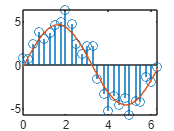

X =     4.6377
    0.9895
    6.2338


f_current = 25.6557

delta = 0.0862

count = 39

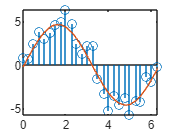

X =     4.6491
    0.9898
    6.2329


f_current = 25.5760

delta = 0.0798

count = 40

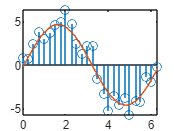

X =     4.6600
    0.9901
    6.2320


f_current = 25.5022

delta = 0.0738

count = 41

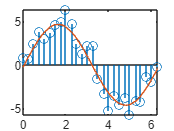

X =     4.6706
    0.9903
    6.2311


f_current = 25.4339

delta = 0.0683

count = 42

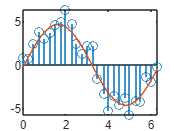

X =     4.6807
    0.9906
    6.2303


f_current = 25.3707

delta = 0.0632

count = 43

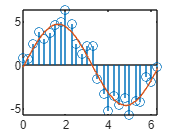

X =     4.6904
    0.9909
    6.2295


f_current = 25.3122

delta = 0.0585

count = 44

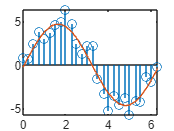

X =     4.6998
    0.9911
    6.2287


f_current = 25.2581

delta = 0.0541

count = 45

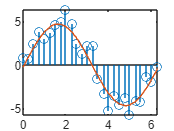

X =     4.7088
    0.9913
    6.2280


f_current = 25.2080

delta = 0.0501

count = 46

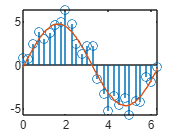

X =     4.7175
    0.9916
    6.2273


f_current = 25.1617

delta = 0.0463

count = 47

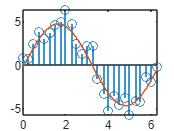

X =     4.7258
    0.9918
    6.2266


f_current = 25.1188

delta = 0.0429

count = 48

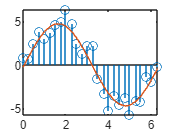

X =     4.7338
    0.9920
    6.2260


f_current = 25.0791

delta = 0.0397

count = 49

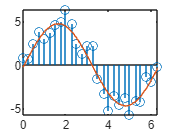

X =     4.7416
    0.9922
    6.2254


f_current = 25.0424

delta = 0.0367

count = 50

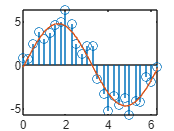

X =     4.7490
    0.9924
    6.2248


f_current = 25.0084

delta = 0.0340

count = 51

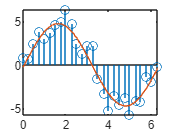

X = 3×1
    4.7561
    0.9926
    6.2242


f_current = 24.9770

delta = 0.0314

count = 52

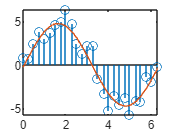

X = 3×1
    4.7630
    0.9927
    6.2236


f_current = 24.9479

delta = 0.0291

count = 53

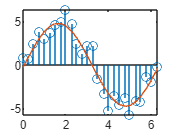

X = 3×1
    4.7696
    0.9929
    6.2231


f_current = 24.9210

delta = 0.0269

count = 54

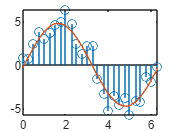

X = 3×1
    4.7760
    0.9931
    6.2226


f_current = 24.8960

delta = 0.0249

count = 55

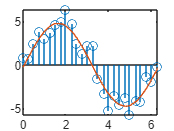

X = 3×1
    4.7821
    0.9932
    6.2221


f_current = 24.8730

delta = 0.0231

count = 56

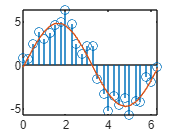

X = 3×1
    4.7880
    0.9934
    6.2217


f_current = 24.8516

delta = 0.0213

count = 57

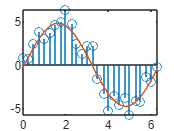

X = 3×1
    4.7936
    0.9935
    6.2212


f_current = 24.8319

delta = 0.0197

count = 58

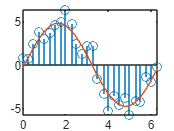

X = 3×1
    4.7991
    0.9937
    6.2208


f_current = 24.8136

delta = 0.0183

count = 59

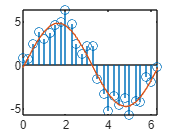

X = 3×1
    4.8043
    0.9938
    6.2204


f_current = 24.7967

delta = 0.0169

count = 60

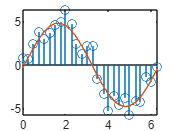

X = 3×1
    4.8094
    0.9939
    6.2200


f_current = 24.7811

delta = 0.0157

count = 61

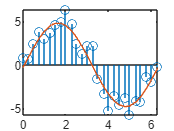

X = 3×1
    4.8142
    0.9940
    6.2196


f_current = 24.7666

delta = 0.0145

count = 62

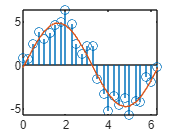

X = 3×1
    4.8189
    0.9942
    6.2192


f_current = 24.7532

delta = 0.0134

count = 63

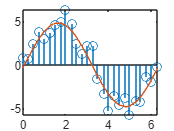

X = 3×1
    4.8234
    0.9943
    6.2189


f_current = 24.7408

delta = 0.0124

count = 64

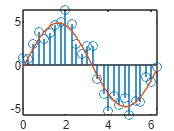

X = 3×1
    4.8277
    0.9944
    6.2185


f_current = 24.7293

delta = 0.0115

count = 65

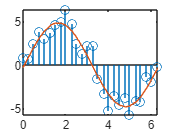

X = 3×1
    4.8318
    0.9945
    6.2182


f_current = 24.7186

delta = 0.0106

count = 66

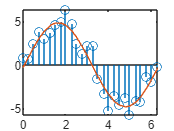

X = 3×1
    4.8358
    0.9946
    6.2179


f_current = 24.7088

delta = 0.0098

count = 67

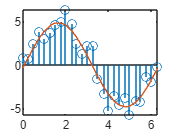


while delta > epsilon
    
    f_prev = f_current;
    X = X - ( (h(X(1),X(2),X(3)) + uk.*I)^(-1) * g(X(1),X(2),X(3)) )
    chol((h(X(1),X(2),X(3)) + uk.*I)^(-1));
    f_current = f(X(1),X(2),X(3))
    delta = abs(f_prev - f_current)
    count = count+1
    figure;
    stem(t,y)
    hold on
    plot(t,X(1)*sin(X(2)*t + X(3)))
    hold off

end